# Signal Visualization and Measurements in MATLAB

This example shows how to visualize and measure signals in the time and frequency domain in 

%x = 3.5*ecg(2700).';
y = repmat(sgolayfilt(x,0,21),[1 13]);
sigData = y((1:30000) + round(2700*rand(1))).';

Display the signal in the time scope and use the Peak Finder, Cursor and Signal Statistics measurements. Assume a sample rate of 4 kHz.

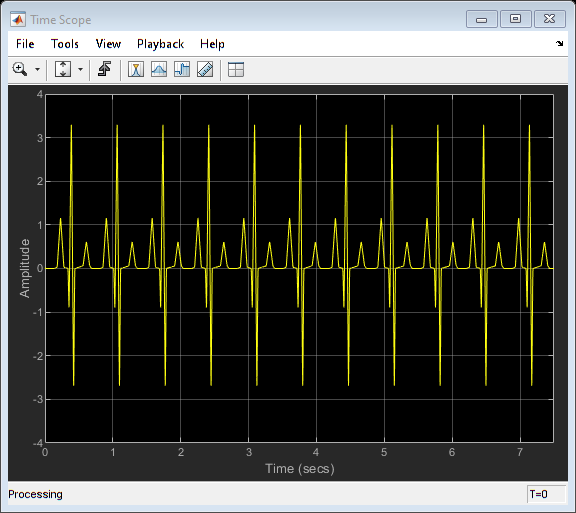

TS_ECG = dsp.TimeScope('SampleRate', 4000, ...
    'TimeSpanSource', 'Auto', 'ShowGrid', true);
TS_ECG(sigData);
TS_ECG.YLimits = [-4, 4];

**Peak Measurements**

Enable **Peak Measurements** by clicking the corresponding toolbar icon or by clicking the **Tools > Measurements > Peak Finder** menu item. Click **Settings** in the Peak Finder panel to expand the Settings pane. Enter `10` for **Max Num of Peaks** and press Enter. The time scope displays in the Peaks pane a list of 10 peak amplitude values and the times at which they occur.

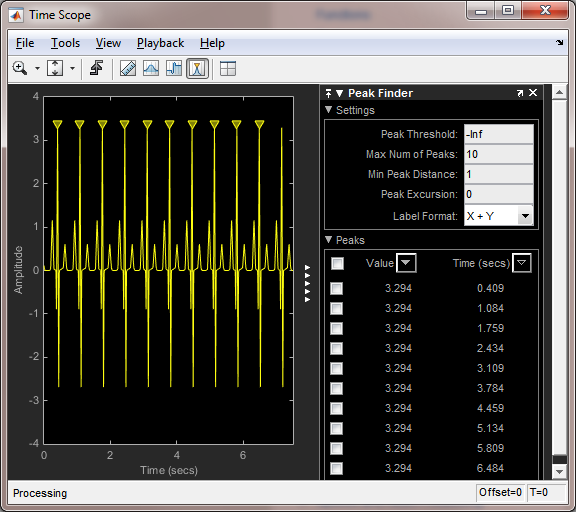

There is a constant time difference of 0.675 seconds between each heartbeat. Therefore, the heart rate of the ECG signal is given by the following equation:


$$\frac{60\,{\rm sec/min}}{0.675\,{\rm sec/beat}} =
88.89\,{\rm beats/min\,(bpm)}$$


**Cursor Measurements** 

Enable **Cursor Measurements** by clicking the corresponding toolbar icon or by clicking the **Tools > Measurements > Cursor Measurements** menu item. The Cursor Measurements panel opens and displays two cursors in the time scope. You can drag the cursors and use them to measure the time between events in the waveform. In the following figure, cursors are used to measure the time interval between peaks in the ECG waveform. The $\Delta T$ measurement in the Cursor Measurements panel demonstrates that the time interval between the two peaks is 0.675 seconds corresponding to a heart rate of 1.482 Hz or 88.9 beats/min.

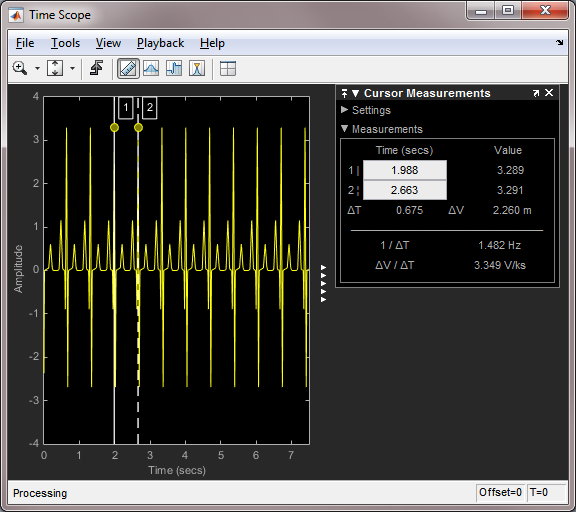

**Signal Statistics** and **Bilevel Measurements**

You can also select **Signal Statistics** and **Bilevel Measurements** from the **Tools > Measurements** menu. Signal Statistics can be used to determine the signal's minimum and maximum values as well as other metrics like the peak-to-peak, mean, median, and RMS values. Bilevel Measurements can be used to determine information about rising and falling transitions, transition aberrations, overshoot and undershoot information, pulse width, and duty cycle. To read more about these measurements, see the [Time Scope Measurements](../examples/time-scope-measurements.html) tutorial example.

*Copyright 2012 The MathWorks, Inc.*